clear;

A1 Initial Guess

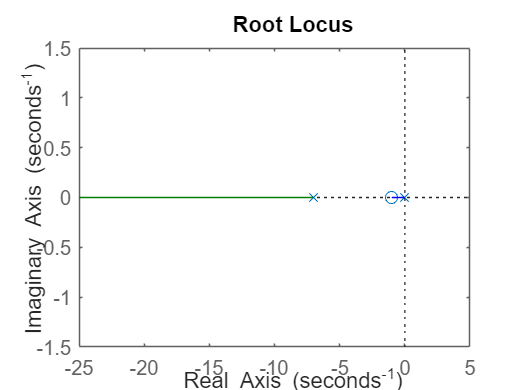

TI = 1;
a = 1.121041;
b = 7;

G = tf([TI 1], [TI 0])*tf([a], [1 b]);
rlocus(G)

The right pole can not lower pass -2, pretty far from -20 (SPEC4).

A2 With the Capability

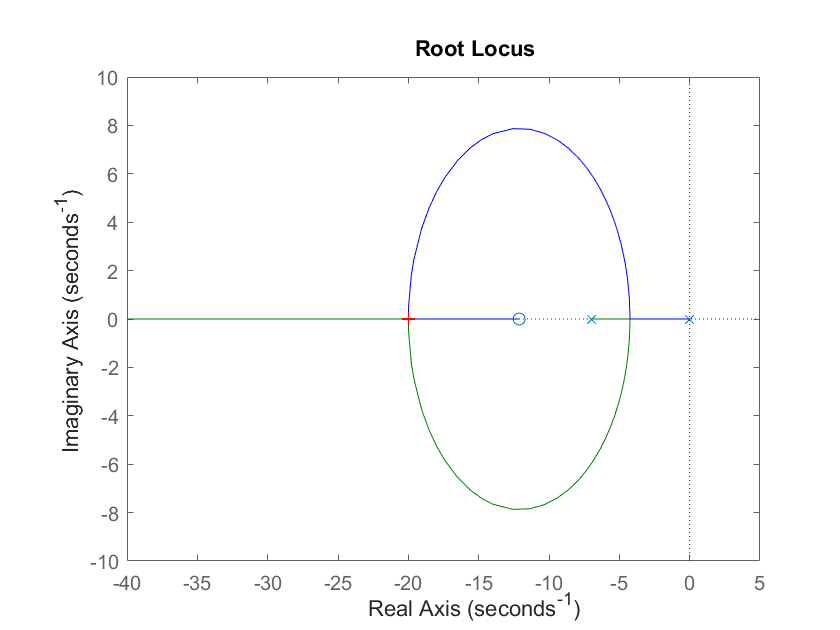

Select a point in the graphics window


selected_point = -19.9882 - 0.0207i

K = 29.4369

poles =  -20.0000 + 0.0170i
 -20.0000 - 0.0170i


TI = 0.0825;
%TI = 0.0725;
a = 1.121041;
b = 7;

G = tf([TI 1], [TI 0])*tf([a], [1 b]);
rlocus(G)
[K, poles] = rlocfind(G)

A3 K and TI found

Run Before Running the Simulink Model

theta = 0;
VMAX_UPM = 11.75;

Run After Running the Simulink Model

A4

% Load the Simulink model
model = 'lab3_sim';
load_system(model);

% Set the solver type to a fixed-step solver
set_param(model, 'SolverType', 'Fixed-step');

% Specify the fixed-step size
fixedStepSize = 0.001;
set_param(model, 'FixedStep', num2str(fixedStepSize));

% Run the simulation
simOut = sim(model);

plot(simout.Time, simout.Data)

xlim([0 2])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Normal Approach")

For Ts Estimation

% Lower bound
0.2 - 0.02*(0.2 - (-0.2))
% Upper bound
0.2 + 0.02*(0.2 - (-0.2))

% Ts = 1.23 s
% Mp = 0.020537
K
TI

% Following is the aggressive approach

A5 Aggressive

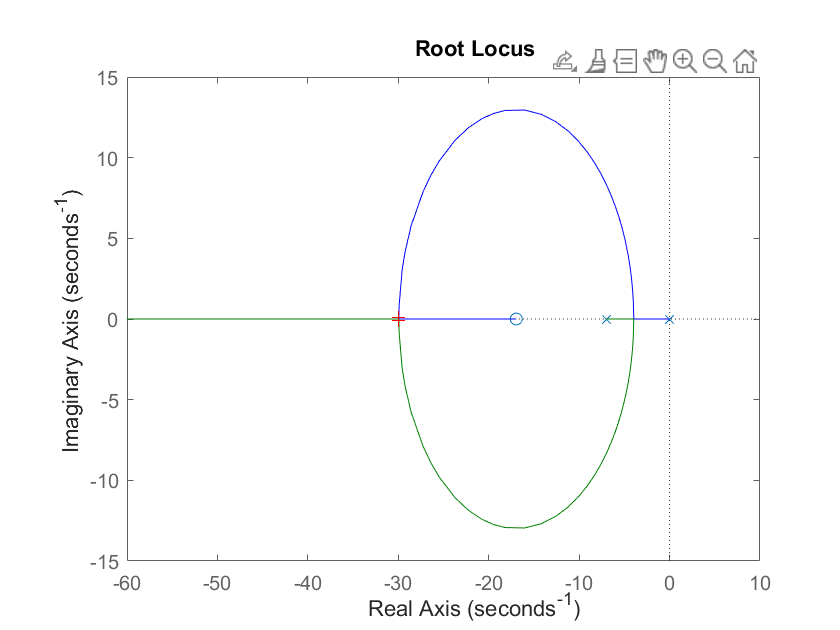

Select a point in the graphics window


selected_point = -29.9763 - 0.0930i

K = 47.1609

poles =  -29.9346 + 0.0828i
 -29.9346 - 0.0828i


TI = 0.059;
a = 1.121041;
b = 7;

G = tf([TI 1], [TI 0])*tf([a], [1 b]);
rlocus(G)
[K, poles] = rlocfind(G)

A6 K and TI found

Run Before Running the Simulink Model

theta = 0;
VMAX_UPM = 11.75;

Run After Running the Simulink Model

A7

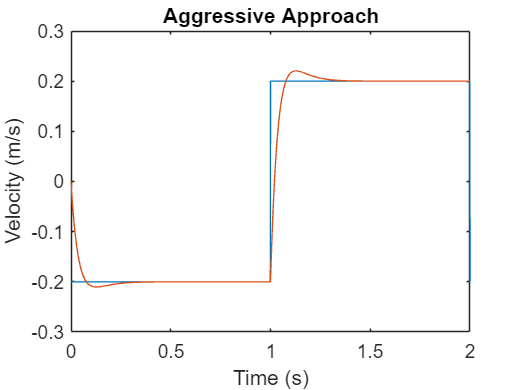

% Load the Simulink model
model = 'lab3_sim';
load_system(model);

% Set the solver type to a fixed-step solver
set_param(model, 'SolverType', 'Fixed-step');

% Specify the fixed-step size
fixedStepSize = 0.001;
set_param(model, 'FixedStep', num2str(fixedStepSize));

% Run the simulation
simOut = sim(model);

plot(simout.Time, simout.Data)
xlim([0 2])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
title("Aggressive Approach")

For Ts Estimation

% Lower bound
0.2 - 0.02*(0.2 - (-0.2))

ans = 0.1920

% Upper bound
0.2 + 0.02*(0.2 - (-0.2))

ans = 0.2080


% Ts = 0.173 s
% Mp = 0.037008
K

K = 29.4369

TI

TI = 0.0825